This function creates a filter that can be applied on a signal to compensate for chromatic dispersion

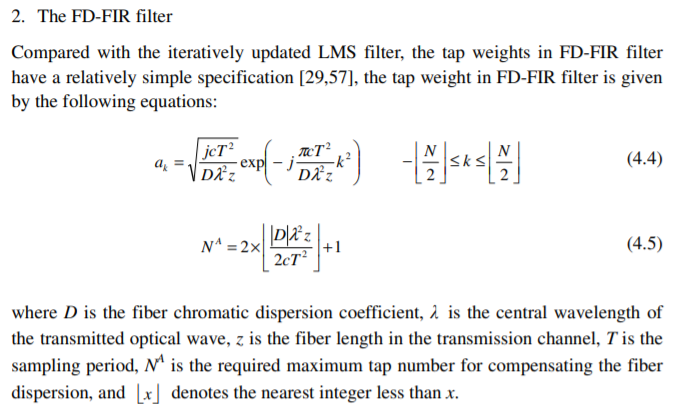

Requires chromatic dispersion coefficient D, wavelength $\lambda$, fiber length z, sampling period T, and max tap number N.

//Hard coded values for simplicity: D, z, $\lambda
$ where D = 16ps/nm/km (typically for optical comms), z = 5000km, $\lambda$ = 1550nm//

function CD_FD_FIR = CD_Filter(sample_rate,D,z,l)

%D = 16*10^(-6); %s/m/m
%z = 5000e3;
lambda = l; %1550*10^(-9);
T = 1/sample_rate;
c = 299792458; % m/s


N = 2*floor((D*z*lambda^2)/(2*c*T^2)) + 1;

k_sqr = (-floor(N/2):floor(N/2)).*(-floor(N/2):floor(N/2));

a_k_amplitude = sqrt((1j*c*T^2)/(D*z*lambda^2));

a_k_exp = (-1j*pi*c*T^2)/(D*z*lambda^2);

CD_FD_FIR = a_k_amplitude * exp((a_k_exp * k_sqr));

end